# **神经网络前馈传播主程序**

%% Initialization
clear ; close all; clc

%% Setup the parameters you will use for this exercise
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10   
                          % (0对应标签10)

%% =========== Part 1: 加载和可视化数据 =============
%  We start the exercise by first loading and visualizing the dataset. 
%  You will be working with a dataset that contains handwritten digits.
% Load Training Data
load('ex1data.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));% 调用可视化函数
fprintf('数据已经加载完成并可视化。\n');

数据已经加载完成并可视化。



%% ================ Part 2: 加载参数 ================
% In this part of the exercise, we load some pre-initialized neural network parameters.
% Load the weights into variables Theta1 and Theta2
load('ex1weights.mat');
fprintf('参数已经加载完成。\n');

参数已经加载完成。



%% ================= Part 3: 实施预测 =================
%  After training the neural network, we would like to use it to predict the labels.
%  You will now implement the "predict" function to use the neural network to predict the labels of the training set.
%  This lets you compute the training set accuracy.
pred = predict(Theta1, Theta2, X);

fprintf('\n Training Set Accuracy: %f\n', mean(double(pred == y)) * 100);


 Training Set Accuracy: 97.575000


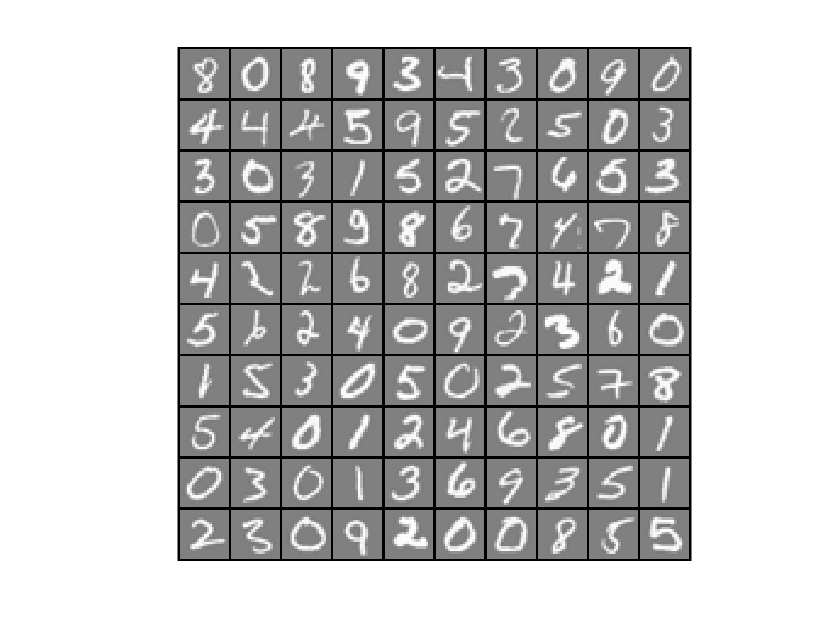

------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 10 (digit 0)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 5 (digit 5)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 3 (digit 3)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 7 (digit 7)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 9 (digit 9)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 5 (digit 5)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 5 (digit 5)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 7 (digit 7)


------------Program paused. Press enter to continue.---------------



Displaying Example Image



Neural Network Prediction: 4 (digit 4)


------------Program paused. Press enter to continue.---------------



Displaying Example Image


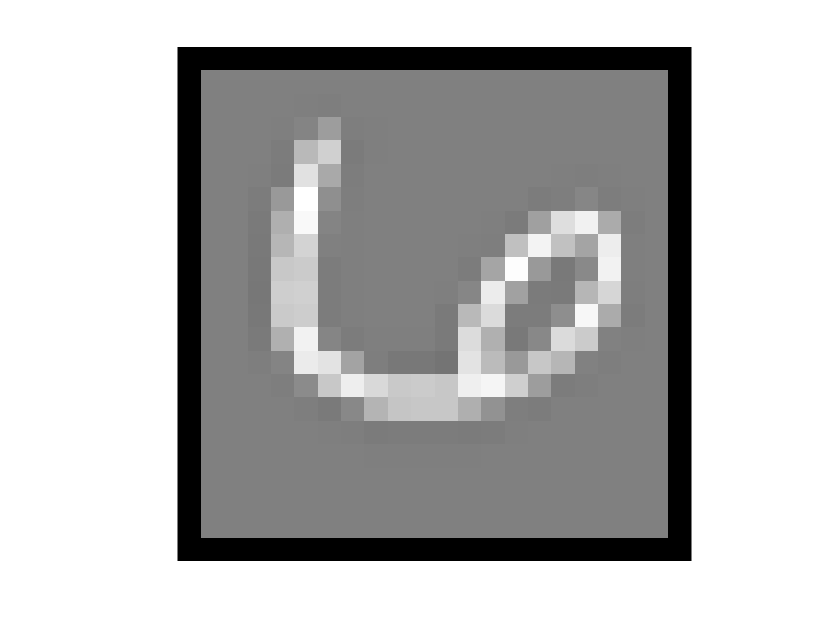


Neural Network Prediction: 6 (digit 6)



%  To give you an idea of the network's output, you can also run through the examples one at the a time to see what it is predicting.
%  Randomly permute examples（随机运行几个例子）
rp = randperm(m);
for i = 1:10
    % 暂停
    fprintf('------------Program paused. Press enter to continue.---------------\n');
    pause;

    % 可视化 
    fprintf('\nDisplaying Example Image\n');
    displayData(X(rp(i), :));

    pred = predict(Theta1, Theta2, X(rp(i),:));
    fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
end